setup parameters

Fs = 44100;     % sample rate
f0 = 440;       % fundamental frequency
k = 1/Fs;       % step size something
L = 10;         % length

c = 2 * L * f0  % wave speed

c = 8800

h = c * k       % h is something related to step size as well

h = 0.1995

N = floor(L/h)  % the actual time step that we use 

N = 50


h = L/N         % recalc of h

h = 0.2000

l = c * k/h     % lambda

l = 0.9977


% state vectors
uNext = zeros(N+1,1);
u = zeros(N+1,1);
uPrev = zeros(N+1,1);

% initializing the excitation of the system
u(33:39) = hann(7);
uPrev = u;

% setting the run time of the system
seconds = 1;
lengthSound = Fs * seconds;


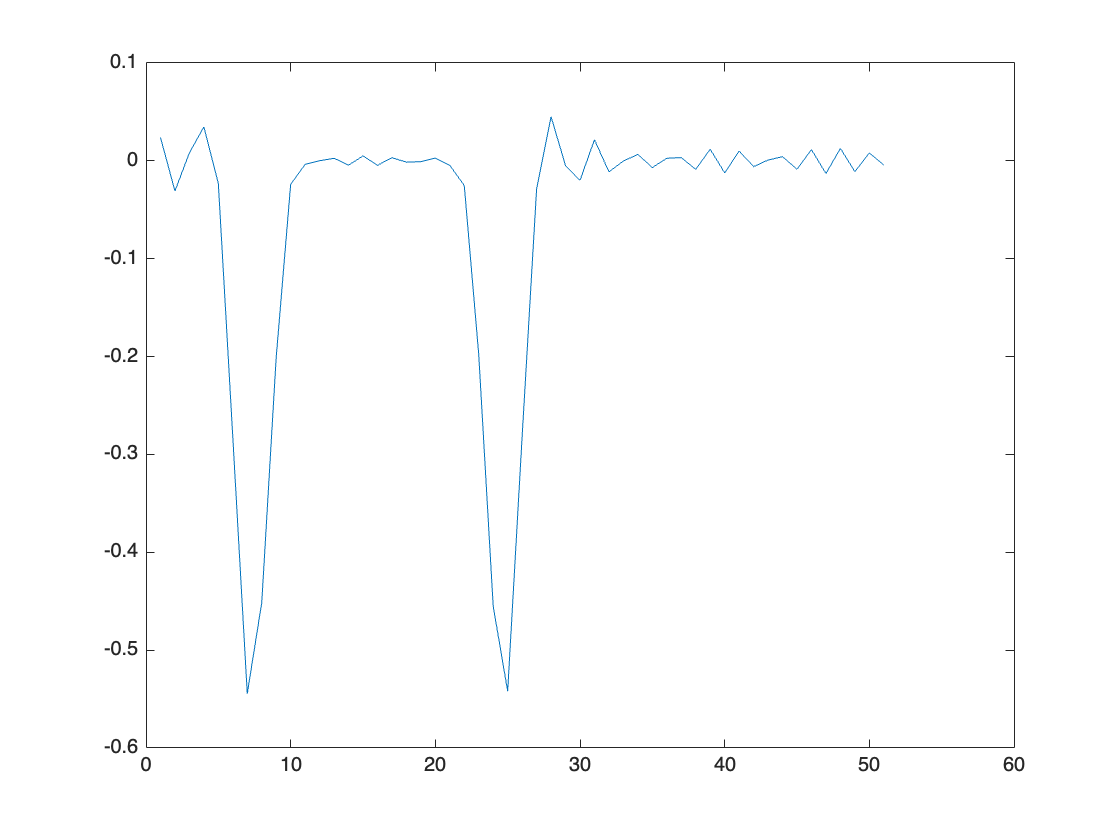

for j = 1:lengthSound
    for i = 1:(N+1)
        next = 0;
        prev = 0;

        if (i == 1)
            next = u(i+1);
            prev = 0;
        elseif (i == N+1)
            next = 0;
            prev = u(i-1);
        else
            next = u(i+1);
            prev = u(i-1);
        end

        uNext(i) = 2* u(i) - uPrev(i) + l*l * (next - 2*u(i) + prev);
        
    end
    
    plot(uNext);
    drawnow
    uPrev = u;
    u = uNext;
end